# Comparison between EMS

## Get current folder and add all folders to the path

currentpath = pwd;
currentfolder = strsplit(currentpath,filesep);
while ((~strcmp(currentfolder{end}, 'EMS-aircraft')) && ...
    (~strcmp(currentfolder{end}, 'EMS-aircraft-main')) && ...
    ~isempty(currentfolder{end}))
    currentpath = fileparts(currentpath);
    currentfolder = strsplit(currentpath,filesep);
end
projectpath = currentpath;
addpath(genpath(projectpath))

EMS_sim = [];
column_names = {};

## Get the data folder

folder_data = strcat(projectpath,'\Data\');

# Select the EMS to compare

## PI

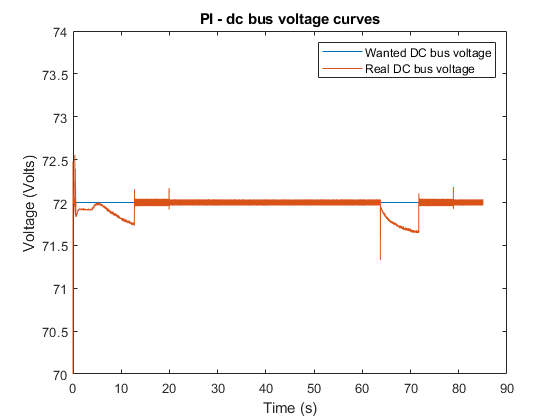

EMS_sim = [EMS_sim; PI];
column_names{end+1} = getVarName(PI);
bus_curve(PI,'PI');

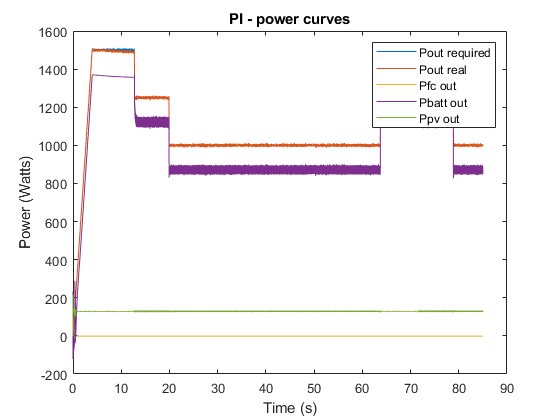

power_curve(PI,'PI');

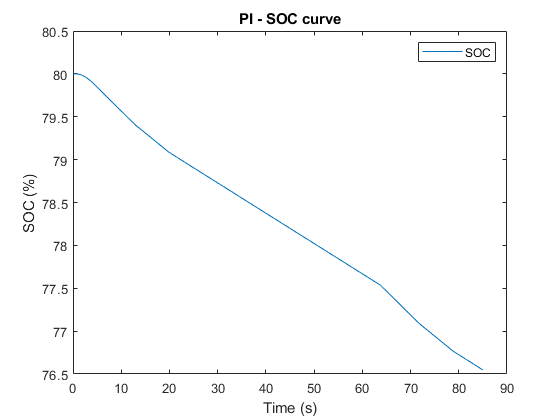

soc_curve(PI,'PI');

## SMC

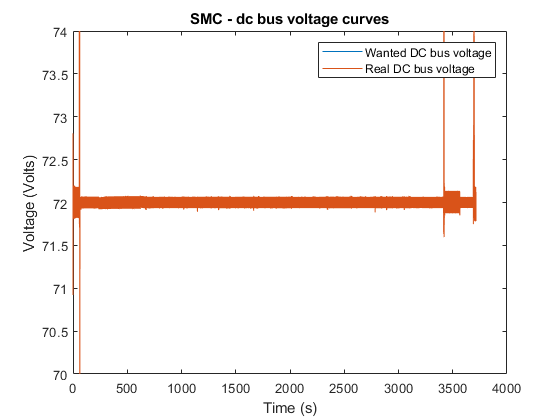

EMS_sim = [EMS_sim; SMC];
column_names{end+1} = getVarName(SMC);
bus_curve(SMC,'SMC');

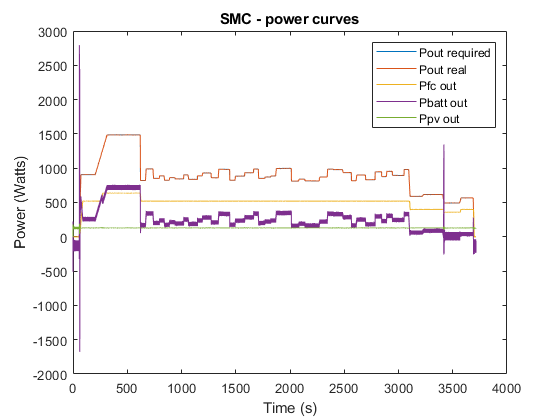

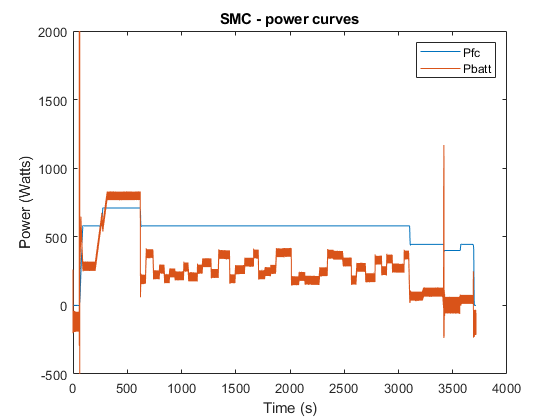

power_curve(SMC,'SMC');

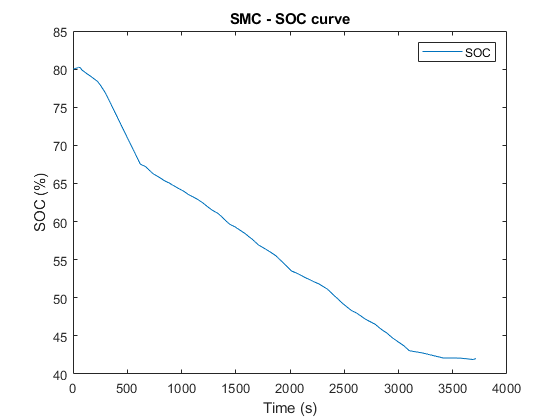

soc_curve(SMC,'SMC');

## FUZZY

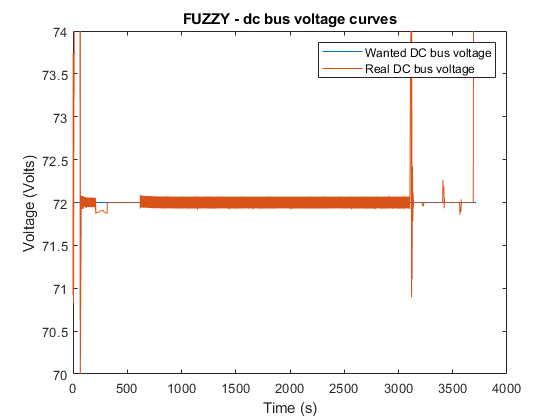

EMS_sim = [EMS_sim; FUZZY];
column_names{end+1} = getVarName(FUZZY);
bus_curve(FUZZY,'FUZZY');

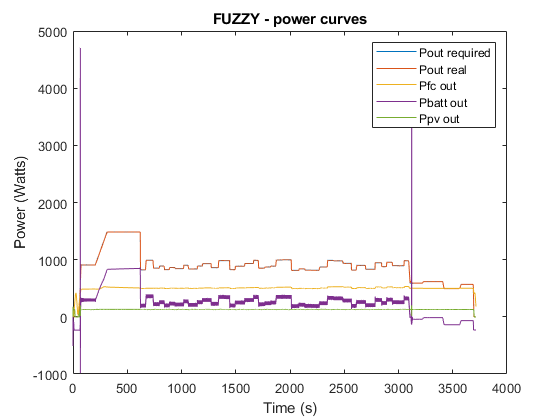

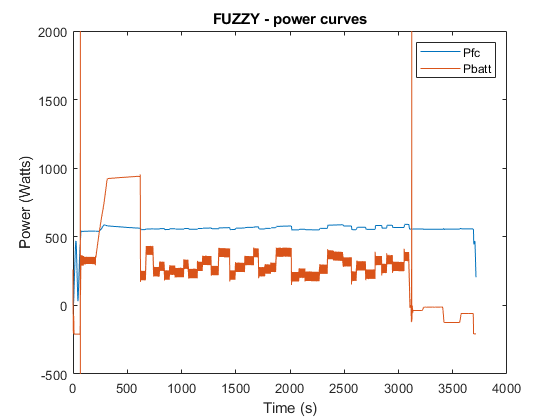

power_curve(FUZZY,'FUZZY');

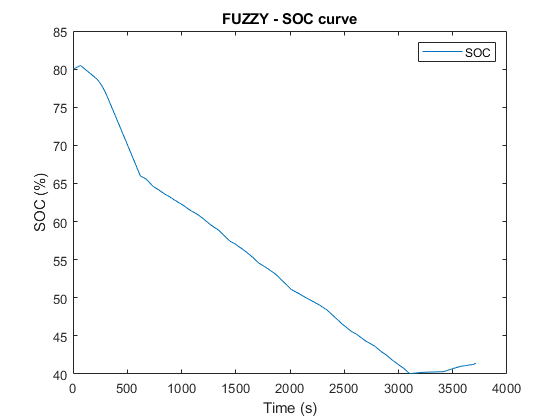

soc_curve(FUZZY,'FUZZY');

## ECMS

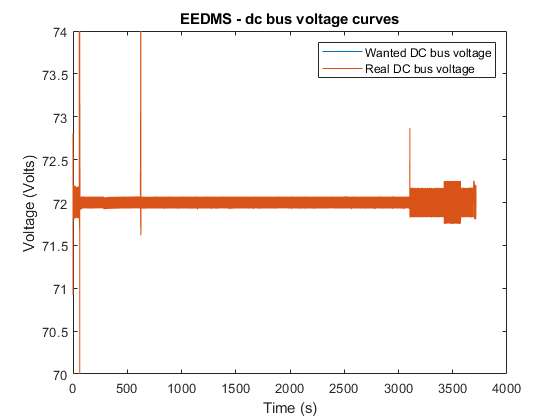

EMS_sim = [EMS_sim; ECMS];
column_names{end+1} = getVarName(ECMS);
bus_curve(ECMS,'EEDMS');

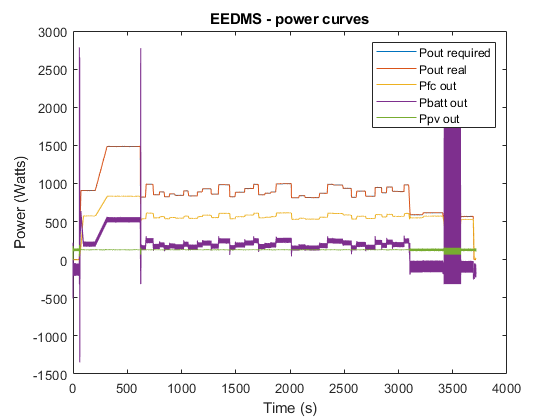

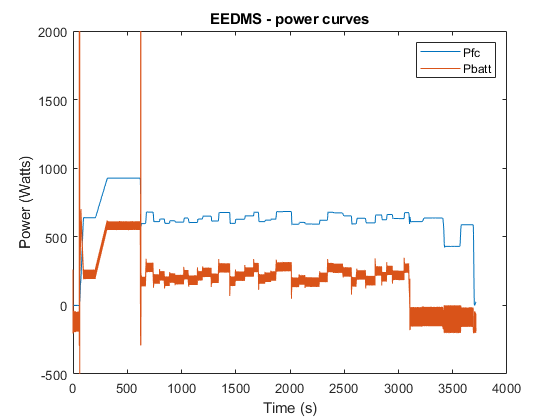

power_curve(ECMS,'EEDMS');

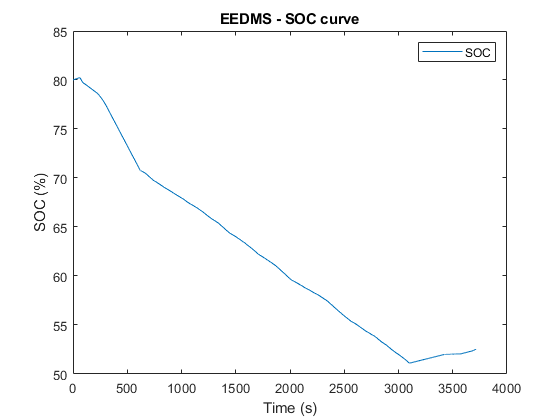

soc_curve(ECMS,'EEDMS');

## EEMS

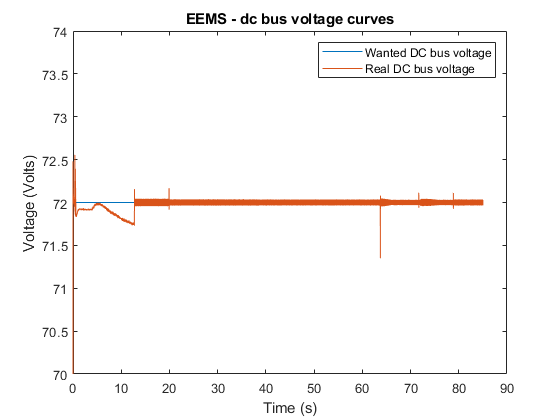

EMS_sim = [EMS_sim; EEMS];
column_names{end+1} = getVarName(EEMS);
bus_curve(EEMS,'EEMS');

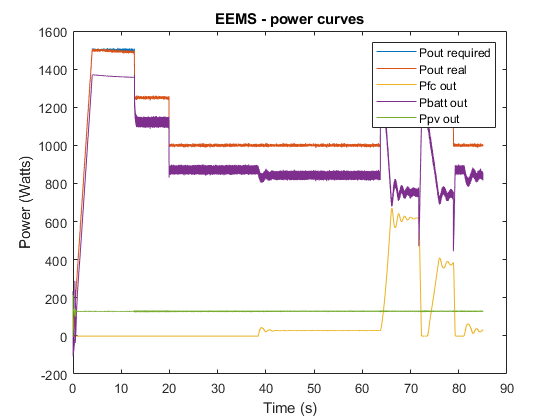

power_curve(EEMS,'EEMS');

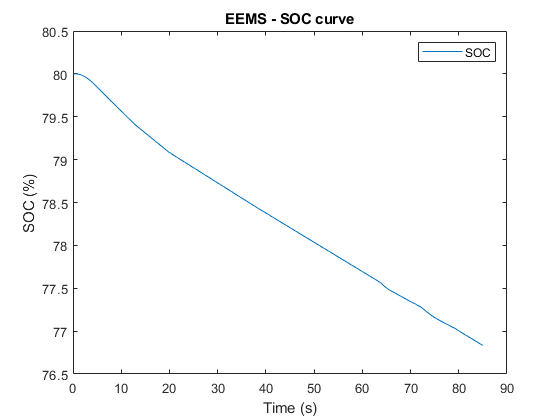

soc_curve(EEMS,'EEMS');

## D-ECMS

% EMS_sim = [EMS_sim; DECMS];
% column_names{end+1} = getVarName(DECMS);
% bus_curve(DECMS,'D-ECMS');
% power_curve(DECMS,'D-ECMS');
% soc_curve(DECMS,'D-ECMS');

## Get the stored data from data file

% tic
% PI = load(strcat(folder_data,'B80_PI_85.mat'));
% SMC = load(strcat(folder_data,'B80_SMC_85.mat'));
% FUZZY = load(strcat(folder_data,'B80_FUZZY_85.mat'));
% ECMS = load(strcat(folder_data,'B80_ECMS_85.mat'));
% toc

# Aligned Curves

## Voltage

% tic
% bus_curve(PI,'PI');
% bus_curve(SMC,'SMC');
% bus_curve(FUZZY,'FUZZY');
% bus_curve(ECMS,'ECMS');
% bus_curve(EEMS,'EEMS');
% bus_curve(DECMS,'DECMS');
% toc

## Power

% tic
% power_curve(PI,'PI');
% power_curve(SMC,'SMC');
% power_curve(FUZZY,'FUZZY');
% power_curve(ECMS,'ECMS');
% power_curve(EEMS,'EEMS');
% power_curve(DECMS,'DECMS');
% toc

## SOC

% tic
% soc_curve(PI,'PI');
% soc_curve(SMC,'SMC');
% soc_curve(FUZZY,'FUZZY');
% soc_curve(ECMS,'ECMS');
% soc_curve(EEMS,'EEMS');
% soc_curve(DECMS,'DECMS');
% toc

# Comparison data tables

## Power mean value

tic
m_power = mean_power(EMS_sim);
row_names = {'Pfc_in','Pfc_out','Pbatt_in','Pbatt_out','Ppv_in','Ppv_out','Psc'};
table_power = array2table(m_power','RowNames',row_names,'VariableNames',column_names)

table_power = 7×1 table
                   ECMS  
                 ________

    Pfc_in         635.05
    Pfc_out        569.89
    Pbatt_in       205.24
    Pbatt_out      182.37
    Ppv_in         144.89
    Ppv_out        129.34
    Psc          -0.30847


toc

Elapsed time is 4.526628 seconds.


## Error mean value

tic
m_error = mean_error(EMS_sim);
row_names = {'RMSE P','RMSE V','MEP (%)','MEV (%)'};
table_error = array2table(m_error','RowNames',row_names,'VariableNames',column_names)

table_error = 4×1 table
                 ECMS  
               ________

    RMSE P       3.4932
    RMSE V      0.25508
    MEP (%)     0.18283
    MEV (%)    0.097339


toc

Elapsed time is 1.200151 seconds.


## Consumption / SOC / SOH / age / sim time

tic
m_consu = consumption(EMS_sim);
row_names = {'H2 cons','SOC','SOH','age','sim time'};
table_consu = array2table(m_consu','RowNames',row_names,'VariableNames',column_names)

table_consu = 5×1 table
                 ECMS  
                _______

    H2 cons      34.631
    SOC          52.525
    SOH         0.72526
    age          0.9379
    sim time          0


toc

Elapsed time is 0.421210 seconds.
